clear all; close all; clc;
load(fullfile("Data", "variableNames.mat"));
load(fullfile("Data", "wavelengths.mat"));

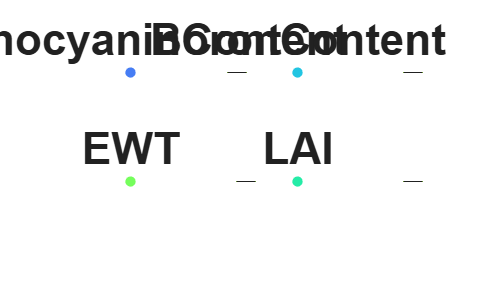

for i = [1, 2, 9, 11]
    load(fullfile("Data/splitDataset/", variables(i)));
    [loadings, scores, eigenVal, t2, explained, mu] = pca(data(:, 2:end));

    rgb = vals2colormap(data(:,1), 'turbo', [min(data(:, 1)), max(data(:,1))]);
    nexttile
    scatter3(scores(:,1), scores(:,2), scores(:,3), 10, rgb, 'LineWidth', 3);
    title(extractBefore(variables(i), "_"));
    xlabel("PC 1");
    limits =[min(scores(:,1)), max(scores(:,1))];
    xlim(limits);
    ylim(limits);
    zlim(limits);
    ylabel("PC 2");
    zlabel("PC 3");
    colormap('turbo');
    colorbar;
    set(gca, 'FontSize', 24)
    set(gca,'CLim',[min(data(:,1)) max(data(:,1))]);
end